# Visualizer

clc

## import ang files

startup_mtex

initialize mtex-6.1.1  ... done!
 
mtex-6.1.1 (show documentation)
  Import pole figure data
  Import EBSD data
  Check Installation
 
  Uninstall MTEX
 


ebsd = EBSD.load('/Users/johnjin/Documents/work/Models/EBSD stiching/EBSD stiching dev dataset/alloy718_aged_1000C_3700s-1_17a.ang')

 
ebsd = EBSD (y↑→x)
 
 Phase   Orientations     Mineral         Color  Symmetry  Crystal reference frame
    -1   111 (0.031%)  notIndexed                                                 
     0  352937 (100%)      Nickel  LightSkyBlue       432                         
 
 Properties: ci, fit, iq, sem_signal, unknown1, unknown2, unknown3, unknown4
 Scan unit : um
 X x Y x Z : [0, 276] x [0, 276] x [0, 0]
 Normal vector: (0,0,1)
 


## plot orientation

  I'm going to colorize the orientation data with the 
  standard MTEX colorkey. To view the colorkey do:
 
  colorKey = ipfColorKey(ori_variable_name)
  plot(colorKey)


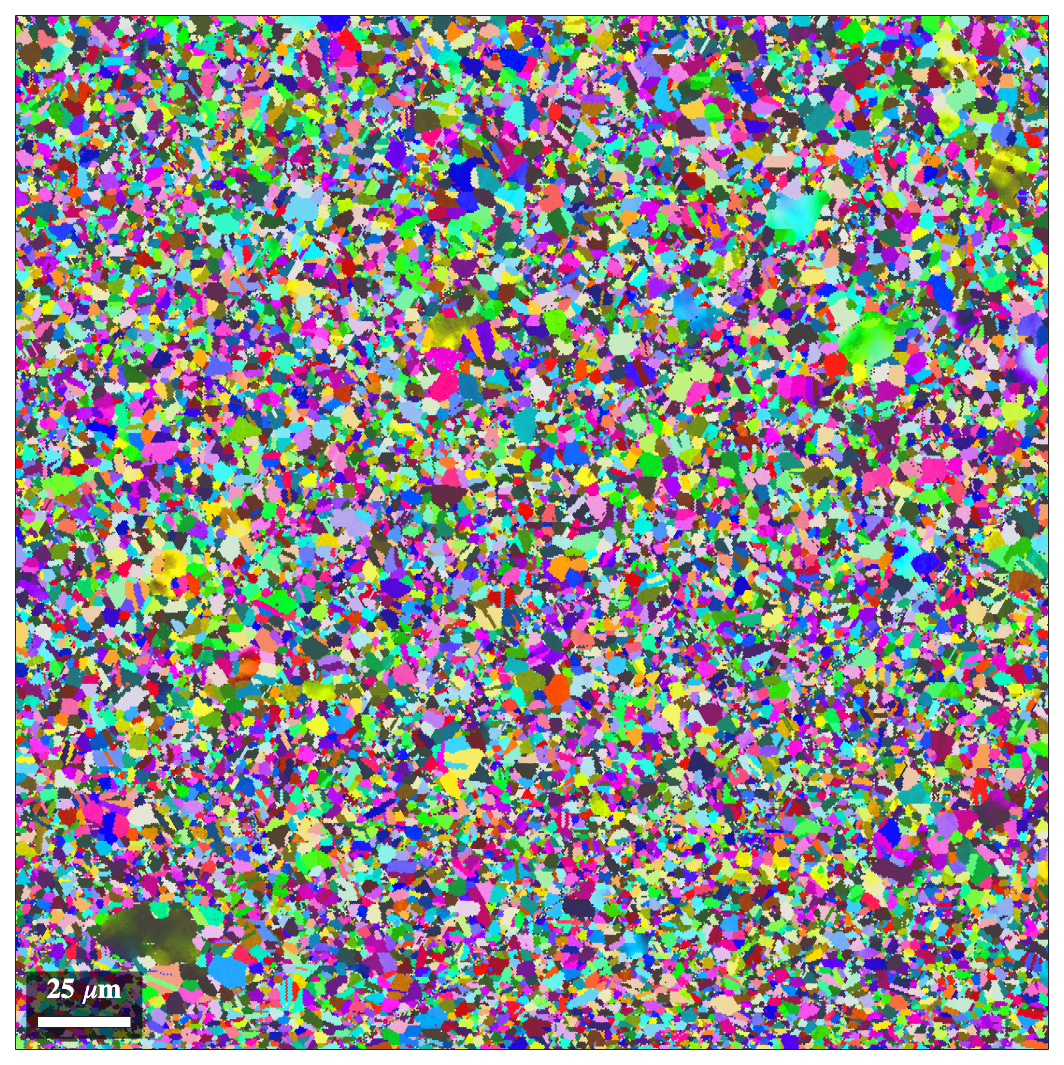

plot(ebsd, ebsd.orientations)

## plot grain boundary

% reconstruct grains
threshold = 10*degree;
minipixel = 5;
grains = calcGrains(ebsd('indexed'),'theshold',threshold,'minPixel',minipixel)

 
grains = grain2d (y↑→x)
 
 Phase  Grains  Pixels  Mineral  Symmetry  Crystal reference frame
     0   13869  320053   Nickel       432                         
 
 boundary segments: 224145 (76674 µm)
 inner boundary segments: 1040 (369 µm)
 triple points: 24723
 
 Properties: meanRotation, GOS
 


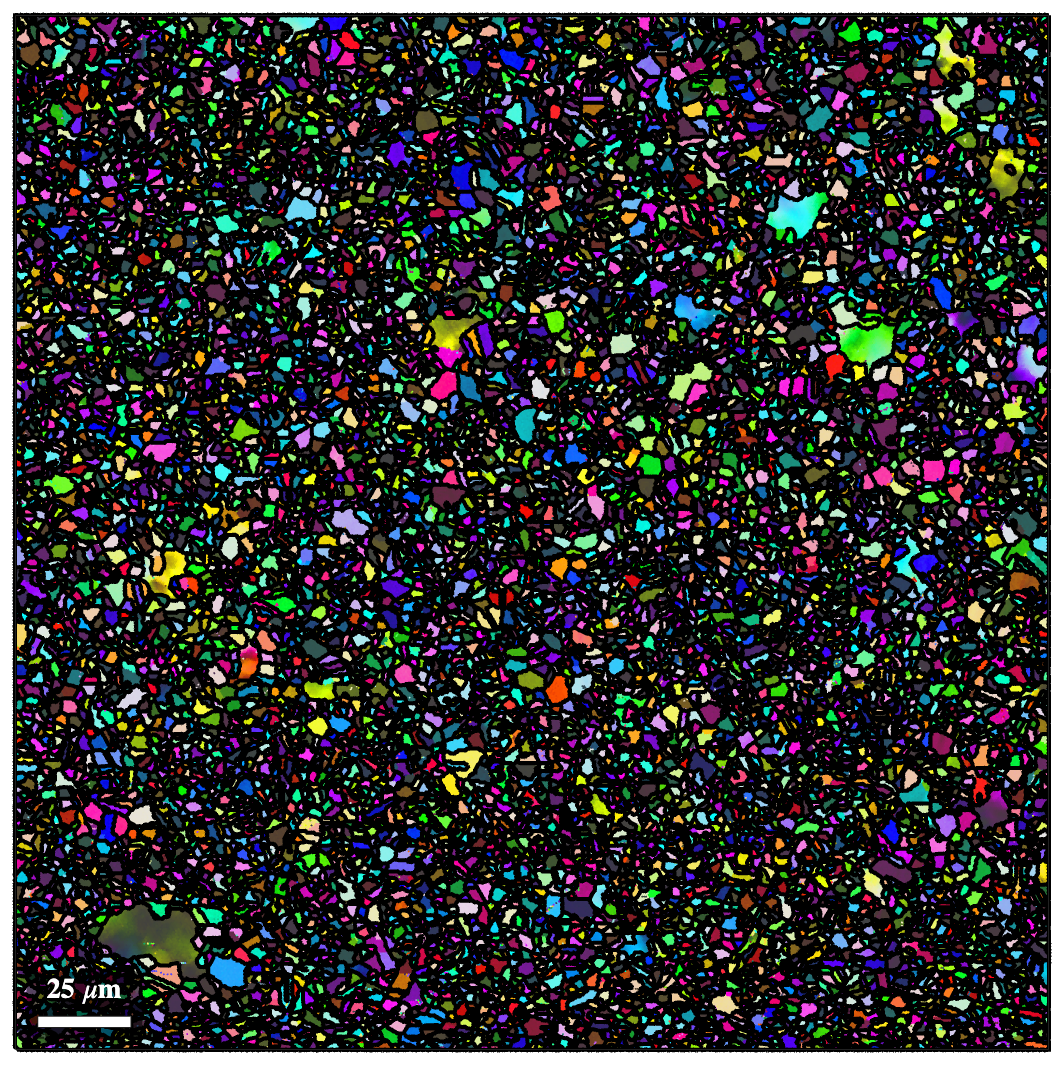


% smooth function
grains = smooth(grains,5);

% plot the grain boundaries
hold on
plot(grains.boundary,'lineWidth',2)
hold off

## plot shape

% define the crystal shape of Forsterite and store it in the variable cS
cS = crystalShape.olivine(ebsd('Austenite').CS)

Error using MTEX
----------------------------------------------------------------
 There are no indexed data in this variable!
 Maybe you misspelled a phase name?
----------------------------------------------------------------


% select only Forsterite grains with more then 100 pixels
grains = grains('Austenite',grains.numPixel > 100);

% plot crystal shapes at the positions of the Forsterite grains
hold on
plot(grains,0.7*cS,'colored')
hold off